# Demodulation and Spectrum Analysis with USRP Radio   

### Configure SDRu Receiver System Object

Set the receive gain in dB.

rxGain = 35.0;
fs = 20e6;
fc = 3410.1e6;
samplesPerFrame = 65536;
% samplesPerFrame = 25536;

Create a receiver System object.

rx = comm.SDRuReceiver(Platform="B210",SerialNum='31577EF',...
    CenterFrequency=fc, ...
    ChannelMapping=1, ...
    Gain=rxGain,...
    MasterClockRate=30720000,...
    TransportDataType='int16', ...
    ClockSource="External",...
    OutputDataType='Same as transport data type',...
    SamplesPerFrame=samplesPerFrame);

Set the decimation factor.

% rx.DecimationFactor = round(rx.MasterClockRate./fs);
rx.DecimationFactor = 1;

Calculate the sample rate by dividing the master clock rate by the decimation factor.

sampleRate = rx.MasterClockRate./rx.DecimationFactor

sampleRate = 30720000

Ts = 1/sampleRate;

Set the desired frame duration.

frameDuration = samplesPerFrame.*(1/sampleRate);

Create a spectrum analyzer System object to visualize the captured signal.

spectrumScope = spectrumAnalyzer(SampleRate=actualSampleRate,...
    ViewType="spectrum-and-spectrogram",SpectrumType="power",...
    Name="B200 Captures",Position=[1000 500 1000 1000],...
    PlotAsTwoSidedSpectrum=true,Method="welch",...
    AveragingMethod="exponential",SpectrumUnits="dBFS",...
    FullScaleSource="property",FullScale=2^11,...
    AxesScaling="manual",YLimits=[-70 -25],...
    SpectrogramChannel=1,...
    ForgettingFactor=0.95,FrequencyOffset=fc);

Receive the signal.

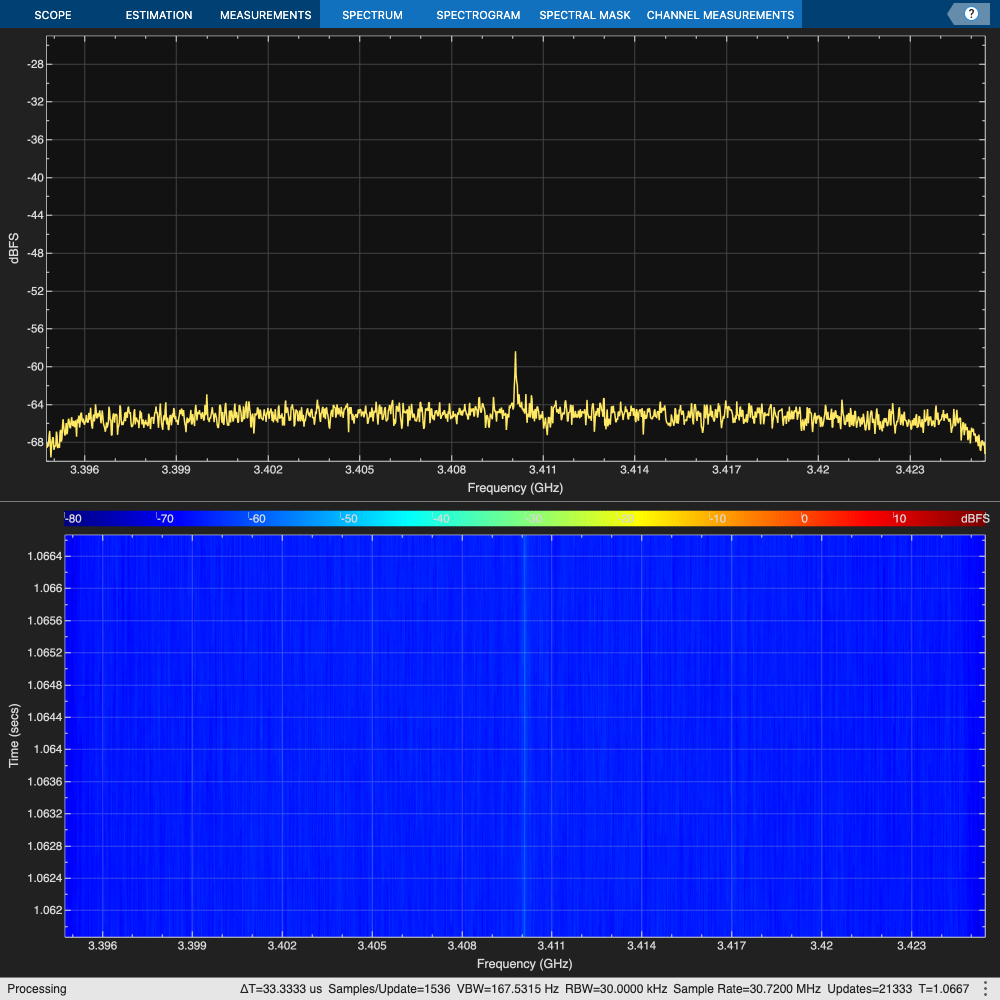

rxWriter = comm.BasebandFileWriter('b200_capture.bb', ...
         sampleRate,rx.CenterFrequency);
overrun = 0; 
for i=1:500
     data = rx();
     rxWriter(data);
     % [iqdata,dataLen,overrun] = rx();     
     spectrumScope(data)     
     drawnow                         
end 

% capture(rx,2,'Seconds','Filename','Recording.bb');
% spectrumScope.TimeSpan = 2;
bbr = comm.BasebandFileReader('b200_capture.bb')

bbr =   comm.BasebandFileReader with properties:

            Filename: '/Users/eric/Radar_Interference_on_5G/b200_capture.bb'
          SampleRate: 30720000
     CenterFrequency: 3.4101e+09
         NumChannels: 1
            Metadata: [1×1 struct]
     SamplesPerFrame: 100
    CyclicRepetition: false


sampleData = bbr()

sampleData = 100×1 int16 column vector
   0 +   0i
   0 +   0i
   0 +   0i
   0 +   0i
   0 +   0i
   0 +   0i
   0 +   0i
   0 +   0i
   0 +   0i
   0 +   0i


% spectrumScope(data)

Release the receiver System object `rx`.

release(rx);

*Copyright 2023 The MathWorks, Inc.*